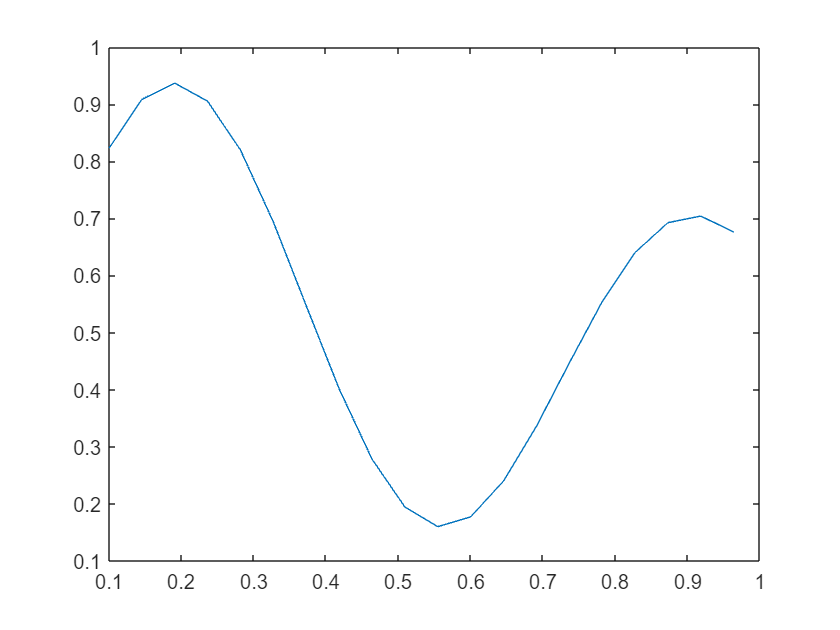

clear
x = (0.1: 1/22: 1)'; %input
n = 0.3; % learning rate
d = (1 + 0.6 * sin (2 * pi * x / 0.7) + 0.3 * sin (2 * pi * x)) / 2;
plot(x, d)

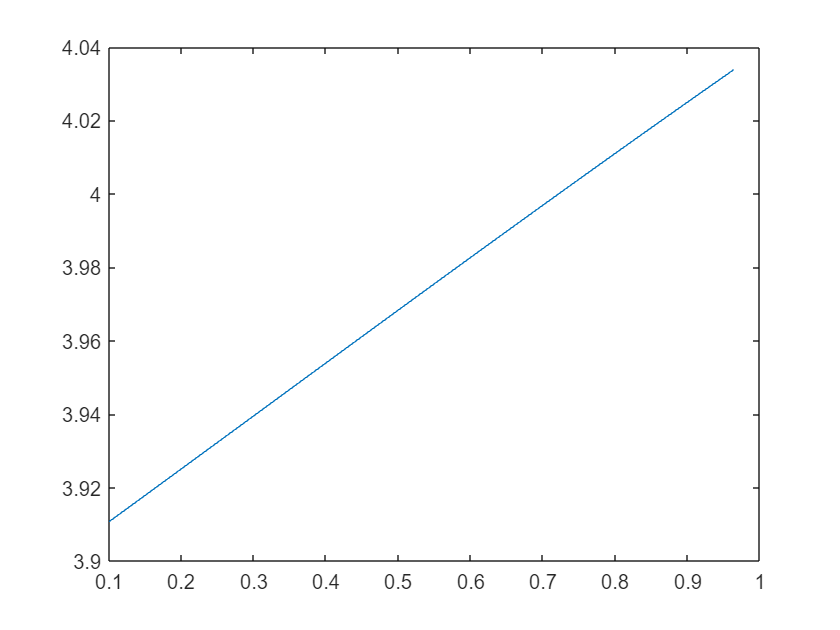


neur_num = 8;
layer_num = 1;
y_dummy = zeros(1); %dummy output

activ_func = @(x_g, w_g, b_g) (1./(1+exp(((-1).*x_g.*w_g) + b_g)));
act_deriv = @(x_g, w_g, b_g) (activ_func(x_g, w_g, b_g).*(1 - activ_func(x_g, w_g, b_g)));

w = rand(layer_num+1, neur_num);
b = rand(layer_num, neur_num);
b_fin = rand(size(y_dummy));

y = sum(activ_func(activ_func(x, w(1, :), b), w(2, :), b_fin), 2);
plot(x, y ...)

     w(1, :) = w(1, :) + (2*(d-y)*act_deriv(x, w, b))

Arrays have incompatible sizes for this operation.

Error in Multi_layer_backpropogation (line 11)
activ_func = @(x_g, w_g, b_g) (1./(1+exp(((-1).*x_g.*w_g) + b_g)));

Error in Multi_layer_backpropogation (line 12)
act_deriv = @(x_g, w_g, b_g) (activ_func(x_g, w_g, b_g).*(1 - activ_func(x_g, w_g, b_g)));

<a href

%     d_weights2 = np.dot(self.layer1.T, (2*(self.y - self.output) * sigmoid_derivative(self.output)))
%     for index = 1:20
%         y_fin(index) = sum(y(:, :, index).*w(2, :));
%     end
%     y_fin = y_fin + b_fin;
%     plot(x, y_fin)
%     e = d - y_fin;
%     if abs(sum(e)) < 0.1
%         break
%     end
%     for index = 1:20
% %         w(2,:) = w(2,:)+n.*e(index).*y(:, :, index);
% %         b21 = b21 + n*e(index);
% %         w(1,:) = w(1,:) + n.*act_deriv(x, w, b, index).*x(index);
% %         b = b + n*act_deriv(x, w, b, index);
%         loss(index) = 2 .* e(index) * act_deriv(x, w, b, index) .* x(index);
% 
%     end
% end